# Método de Falsa Posición

Este Live Script explica e implementa el método de Falsa Posición para encontrar raíces de ecuaciones no lineales.

## Objetivos de aprendizaje

### Objetivos de aprendizaje para docentes/instructores

- Utilizar el script del **método de Falsa Posición** como una herramienta interactiva en clase para:

- **Visualizar** paso a paso el proceso de aproximación de la raíz, reforzando la comprensión teórica mediante gráficas dinámicas.

- **Mostrar en tiempo real** cómo la elección de los límites iniciales afecta la convergencia del método.

- **Facilitar la conexión** entre el planteamiento matemático y su implementación en MATLAB, reduciendo la brecha entre teoría y práctica.

- Aprovechar el script para:

- **Explicar la estructura de un algoritmo numérico** usando un ejemplo concreto.

- **Demostrar buenas prácticas de codificación** en MATLAB (uso de funciones anónimas, funciones personalizadas, bucles y criterios de paro).

- **Promover la participación activa** pidiendo a los estudiantes que modifiquen parámetros y observen los resultados de inmediato.

### **Para estudiantes:**

- Aprender a modificar correctamente un script de MATLAB que utilice:

- Una función anónima (*function_handle*).

- Una función personalizada (definida dentro de un script).

- Utilizar de forma adecuada un bucle `while` con una condición de paro.

- Aproximar la raíz de una ecuación no lineal (1 ecuación con 1 incógnita) empleando el **método de Falsa Posición**.

## Instrucciones de uso del script

### **Modo de visualización recomendado**

- Ejecute el Live Script en **MATLAB** utilizando el modo **Output inline** (*Output → Inline*).Esto permitirá que el código y los resultados (gráficas, tablas y textos) aparezcan juntos en el mismo documento, facilitando la comprensión paso a paso.

### **Ejecución por secciones**

- Es recomendable ir ejecutando el script **por secciones**, usando los botones **Run Section** o **Run and Advance** en la barra de herramientas.

Esto le permitirá:

- Analizar y comprender el efecto de cada bloque de código.

- Visualizar cómo se van actualizando las gráficas y las variables.

- Realizar modificaciones en los valores de entrada (función, límites iniciales, tolerancia, etc.) y ver de inmediato su impacto en los resultados.

## Descripción

El método de Falsa Posición (también llamada método de interpolación lineal) es otro método de intervalos bien conocido. Es muy similar al método de Bisección con la excepción de que utiliza una estrategia diferente para llegar a su nueva raíz aproximada. En lugar de bisecar el intervalo, localiza la raíz uniendo **f(xl)** y **f(xu)** con una línea recta. La intersección de esta línea con el eje x representa una estimación mejorada de la raíz.

Si una función cambia de signo durante un intervalo, se evalúa el valor de la función en el punto estimado de **xr**. Luego se determina que la ubicación de la raíz se encuentra dentro del subintervalo donde ocurre el cambio de signo. El subintervalo se convierte entonces en el intervalo para la siguiente iteración. El proceso se repite hasta que se conoce la raíz con la precisión requerida.

En general, si **f(x)** es real y continúa en el intervalo que va desde un límite inferior (**xl**) hasta un límite superior (**xu**) y **f(xl)** y **f(xu)** tienen signos opuestos, es decir:

## 
$$f(x_{l})*f(x_{u})<0$$
 

Entonces hay al menos una raíz real entre **xl** y **xu**.

## Definición de los parámetros de entrada

El primer paso consiste en la definición de la función a solicionar, para ello considere como ejemplo la siguiente función:


$$\[-0.5x^{2}+2.5x+4.5\]$$


 Copie y pegue en el siguiente cuadro la funcion: **@(x)-0.5.*x.^2 + 2.5.*x + 4.5**

func=@(x)-0.5.*x.^2 + 2.5.*x + 4.5; %Función de la cual se desea conocer las raices

## Métodos Gráficos

Un método simple para obtener una aproximación a la raíz de la ecuación *f (x) = 0 *consiste en graficar la función y observar dónde cruza el eje x. Este punto, que representa el valor de x para el cual *f(x) = 0*, ofrece una aproximación inicial de la raíz y permite establecer los valores iniciales de **xl** y **xu**.

- Valor del límite inferior para los ejes de la gráfica

lin = -10; %Valor del límite inferior para los ejes de la gráfica

- Valor del límite superior para los ejes de la gráfica

lsup = 10;%Valor del límite superior para los ejes de la gráfica

- Paso o resolución para el gráfico

paso = 0.1; %Paso o resolución para el gráfico

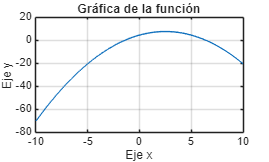

x=(lin:paso:lsup);
y = func(x);
plot(x,y);
title('Gráfica de la función') %Título de la gráfica
xlabel('Eje x') %Título del eje x de la gráfica
ylabel('Eje y') %Título del eje y de la gráfica
grid on; %Activa la cuadricula en la gráfica

Una vez definida la función de la cual se desea conocer la raíz que cumpla que *f(x) = 0*, se puede iniciar con el algoritmo del método de Falsa Posición.

## Paso 1

Se elijen los valores iniciales inferior, **x**l, y superior, **xu**, que encierren la raíz, de forma tal que la función cambie de signo en el intervalo. 

xl = -5;
xu = 0;

Una vez definidos los valores de **xl** y **xu** se verifica que

## 
$$f(x_{l})*f(x_{u})<0$$
 

test = func(xl)*func(xu);
test1=-92.25;
if test>0
    disp1='no hay cambio de signo';
elseif test<0
    disp1='si hay cambio de signo';
end
disp1;
'si hay cambio de signo';

### **Nota:**

Con los limites propuestos queda demostrado que la raíz posee signo negativo. Haga un pequeño cambio en los límites, utilizando xl=0 u xu=5 y observe que sucede con la verificación del cambio de signo. ¿Qué debería suceder?

## Paso 2

Usando triángulos semejantes, la intersección de la línea recta con el eje x se puede estimar como:

## 
$$x_{r}=x_{u}-\frac{f(x_{u})\left ( x_{l}-x_{u} \right )}{f(x_{l})-f(x_{u})}$$


xr=xu-(func(xu)*(xl-xu))/(func(xl)-func(xu)); %Cálculo del valor de xr
xr0=-2.5;

## Verificación gráfica de los limites xl y xu

El método de Falsa Posición aprovecha el hecho de que una función cambia de signo en la vecindad de una raíz. A estas técnicas se les llama *métodos cerrados*, o de *intervalos*, porque se necesita de dos valores iniciales para la raíz. Como su nombre lo indica, dichos valores iniciales deben “encerrar”, o estar a ambos lados de la raíz.

### Actividad:

Modifique la posicion de los limites inferior y superior para que observe como estos se van acercando cada vez mas hasta encontrar la convergencia.

xl1=-4.7;
xu1=-0.9;

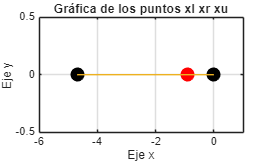

A = [xl1 xu1];
B = [0  0];
C1 = xr;
C2 = 0;
plot(A,B,'-o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','k')
grid on
axis1 = (xl-1);
axis2 = (xu+1);
axis([axis1 axis2 -0.5 0.5])
hold on
plot(C1,C2,'-o','MarkerSize',10,'MarkerEdgeColor','r','MarkerFaceColor','r')
line(A,B)
hold off
title('Gráfica de los puntos xl xr xu') %Título de la gráfica
xlabel('Eje x') %Título del eje x de la gráfica
ylabel('Eje y') %Título del eje y de la gráfica
grid on; %Activa la cuadricula en la gráfica

## Paso 3

Se realiza la siguiente evaluación para determinar en qué subintervalo está la raíz:

## 
$$f(x_{l})*f(x_{r})$$


El subintervalo en el que se encuentra la raíz se selecciona de la siguiente forma:

**a)** Si *f(xl)f(xr) < 0*, entonces la raíz se encuentra dentro del subintervalo inferior o izquierdo. Por lo tanto, se establece **xu = xr** y se vuelve al paso 2.

**b)** Si *f(xl)f(xr) > 0*, entonces la raíz se encuentra dentro del subintervalo superior o derecho. Por lo tanto, se establece **xl = xr** y se vuelve al paso 2.

**c)** Si *f(xl)f(xr) = 0*, la raíz es igual a **xr**; se termina el cálculo.

test2 = func(xl)*func(xr);
-37.8225

ans =                   -37.8225


% Update the bounds based on the test results
if test2 < 0
    xu = xr; % Update upper bound
elseif test2 > 0
    xl = xr; % Update lower bound
elseif test2 == 0
xr = 0
end

## Iteración 2

Una vez que se determina el intervalo en el cual se encuentra la raíz mediante el paso 3, se vuelve al paso 2 para determinar el nuevo valor de **xr**.

xrold = xr;
xr = xu-(func(xu)*(xl-xu))/(func(xl)-func(xu))

xr =          -1.23853211009174


## Criterios de paro y estimaciones de errores

El método se repite para obtener una aproximación más exacta de la raíz. Se debe desarrollar un criterio objetivo para decidir cuándo debe terminar el método.

Se requiere estimar el error de forma tal que no se necesite el conocimiento previo de la raíz, esto es posible calculando el error relativo porcentual de la siguiente manera:

## 
$$\varepsilon_{a}=\left| \frac{x_{r}^{nuevo}-x_{r}^{anterior}}{x_{r}^{nuevo}} \right|*100% $$


ea = abs((xr - xrold)/xr) * 100

ea =           27.3333333333333


## Implementación del Método de Falsa Posición

A continuación se muestra un código ejemplo que implementa el método de Falsa Posición para determinar la raíz de una función.

Es = 0.01; %Criterio de paro para el método de Falsa Posición
Resultados = FalsaPosicion(func,xl,xu,Es)

Resultados = 8×8 table
    i    xl           xu                   xr            f(xl)           f(xr)                f(xl)*f(xr)                 ea         
    _    __    _________________    _________________    _____    ____________________    ____________________    ___________________

    1    -5                 -0.9    -1.23853211009174    -20.5        0.63668883090649        -13.052121033583       303.703703703704
    2    -5    -1.23853211009174    -1.35183673469388    -20.5       0.206676884631404       -4.23687613494377       8.38153171120862
    3    -5    -1.35183673469388    -1.38824967639868    -20.5      0.0657572269927922       -1.34802315335224       2.62293896579611
    4    -5    -1.38824967639868  

function Resultados = FalsaPosicion(f,xl,xu,Es)
xr=xl; % Da un valor inicial a xr
iter=0; % variable de conteo de iteraciones
ea=100;
R=[]; %Matriz que contendrá los datos para realizar la tabla
    while (1) %Ciclo while para realizar las iteraciones
        xrold=xr; %Definición incial de xr
        xr=xu-(f(xu)*(xl-xu))/(f(xl)-f(xu)); %Cálculo del xr nuevo para el método de Falsa Posicion
        iter=iter+1; %Incremento del número de iteración.
        fxlxr=f(xl)*f(xr); %Cálculo de la función evaluada en xl y xr para ver si hay cambio de signo
        if xr ~= 0 %Si xr es distinto a 0, se calcula el valor del error aproximado
        ea = abs((xr - xrold)/xr) * 100;
        end
        F=[iter xl xu xr f(xl) f(xr) fxlxr ea]; %Vector fila con los datos de cada iteración
        %F=[iter xl f(xl) xu f(xu) xr f(xr) ea]; %Vector fila con los datos de cada iteración
        R=[R;F]; %Adición del vector fila F a la tabla con los resultados del programa.
        producto = f(xl)*f(xr); %Variable para verificar el producto de f(xl) y f(xu)
        if producto < 0 %Si el producto es menor a 0, xu se sustituye por xr
        xu = xr;
        elseif producto > 0 %Si el producto es mayor a 0, xl se sustituye por xr
        xl = xr;
        else
        ea = 0; %Si el error absoluto es igual a 0, el ciclo termina (eso indica que ya se encontró el valor de xr
        %para la cual la función es 0, por tanto en ese caso xr sería la raíz). 
        end
        if ea <= Es %Si el error relativo aproximado es menor que la tolerancia, se termina el método. 
            break
        end
    end
Resultados=array2table(R,'VariableNames', {'i' 'xl' 'xu' 'xr' 'f(xl)' 'f(xr)' 'f(xl)*f(xr)' 'ea'}); %Creación de la tabla
end

Creado por Adrián Quesada Martínez 2023.